Settings

Alles löschen

clear
clc

LaTex-Interpreter als Standard für Grafiken setzen

set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultAxesTickLabelInterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

Schriftgröße für Grafiken setzen

set(groot, 'defaultTextFontSize', 11)
set(groot, 'defaultAxesFontSize', 11)
set(groot, 'defaultLegendFontSize', 11)

Verzeichnis wechseln (in Verzeichnis des Live-Skripts)

cd(fileparts(matlab.desktop.editor.getActiveFilename))

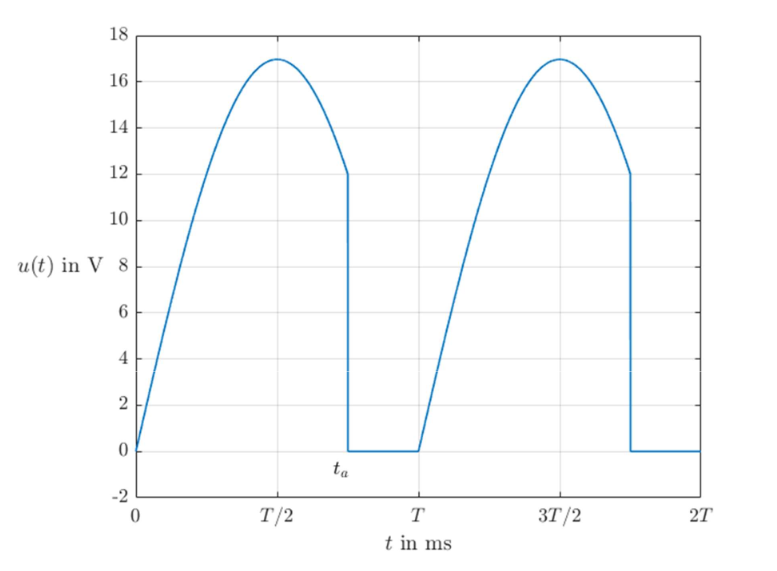

Zahlenwerte von u(t)

u_p.U_p = 12 * sqrt(2);
u_p.f = 50;
u_p.T = 1 / u_p.f;
u_p.t_a = 0.3 * u_p.T;
u_p

u_p = struct with fields:
    U_p: 16.9706
      f: 50
      T: 0.0200
    t_a: 0.0060


Zeitvektor für Darstellung, 2 perioden

u_p.t = -10e-3 : 1e-6 : 40e-3;
t = linspace(0,50e-3,1000)

t =          0    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0010    0.0010    0.0011    0.0011    0.0012    0.0012    0.0013    0.0013    0.0014    0.0014    0.0015    0.0015    0.0016    0.0016    0.0017    0.0017    0.0018    0.0018    0.0019    0.0019    0.0020    0.0020    0.0021    0.0021    0.0022    0.0022    0.0023    0.0023    0.0024    0.0024    0.0025


u_p.u_t = abs(u_p.U_p .* sin(pi * u_p.f .* u_p.t) .* ...
                ((u_p.t >= 0 & u_p.t <= u_p.t_a) | ...
                 (u_p.t >= u_p.T & u_p.t <= u_p.T + u_p.t_a) | ...
                 (u_p.t >= 2 * u_p.T)));

Grafische Darstellung

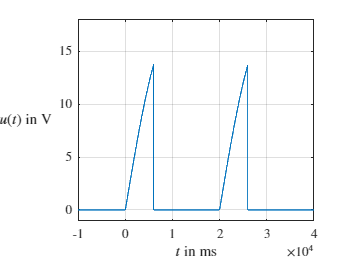

figure

plot(u_p.t * 1e6, u_p.u_t)
grid('on')
ylim([-1, 18])

xlabel('$t$ in ms')
ylabel('$u(t)$ in V')

set(get(gca, 'ylabel'), 'Rotation', 0, 'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle')

## Bestimmung der Fourier-Koeffizienten

Die Koeffizienten für die komplexe Form der Fourier-Reihe werden über die Formel

    
$${\hat{\underline{u} } }_k =\frac{1}{T}\int_{t=t_0 }^{t_0 +T} u\left(t\right){\mathrm{e}}^{-\mathrm{j}{k\omega }_0 \;t} \mathrm{d}\;t$$


bestimmt. 

Hier wird $t_0 =0$ gewählt. Innerhalb der Periodendauer zwischen $0$ und $t_a$ ist die Spannung nur für $t\le T_a$ ungleich null, und zwar eine sinsusförmige. Damit ist das folgende Integral zu lösen.

    
$${\hat{\underline{u} } }_k =\frac{1}{T}\int_{t=0}^{t_a } \hat{u} \cdot \sin \left(\omega_0 \cdot t\right){\;\cdot \;\mathrm{e}}^{-\textrm{jk}\omega_0 \;t} \textrm{dt}$$


syms('t', 'omega_0', 'T', 'f', 't_a', 'U_p', 'positive')
syms('k', 'integer')
u_p_k = 1 / T * int(U_p * sin(pi*f*t) * exp(-1j * k * omega_0 * t), t, [0, t_a])

$$u\_p\_k = -\frac{\frac{U_{p}\,{\mathrm{e}}^{-k\,\omega_{0}\,t_{a}\,\mathrm{i}}\,\left(\pi \,f\,\cos\left(\pi \,f\,t_{a}\right)+k\,\omega_{0}\,\sin\left(\pi \,f\,t_{a}\right)\,\mathrm{i}\right)}{f^{2}\,\pi^{2}-k^{2}\,{\omega_{0}}^{2}}-\frac{\pi \,U_{p}\,f}{f^{2}\,\pi^{2}-k^{2}\,{\omega_{0}}^{2}}}{T}$$

u_p_k = simplify(u_p_k)

$$u\_p\_k = -\frac{\frac{U_{p}\,{\mathrm{e}}^{-k\,\omega_{0}\,t_{a}\,\mathrm{i}}\,\left(\pi \,f\,\cos\left(\pi \,f\,t_{a}\right)+k\,\omega_{0}\,\sin\left(\pi \,f\,t_{a}\right)\,\mathrm{i}\right)}{f^{2}\,\pi^{2}-k^{2}\,{\omega_{0}}^{2}}-\frac{\pi \,U_{p}\,f}{f^{2}\,\pi^{2}-k^{2}\,{\omega_{0}}^{2}}}{T}$$

Berechnung Gleichanteil

u_p_0 = subs(u_p_k, k, 0)

$$u\_p\_0 = \frac{\frac{U_{p}}{f\,\pi }-\frac{U_{p}\,\cos\left(\pi \,f\,t_{a}\right)}{f\,\pi }}{T}$$

numerische Berechnung der Fourier-Koeffizienten


u_p_k_num = subs(u_p_k, [U_p, T, f, omega_0, t_a], [u_p.U_p, u_p.T, u_p.f, 2 * pi * u_p.f, u_p.t_a]);
u_p_k_num = simplify(u_p_k_num)

$$u\_p\_k\_num = \begin{array}{l} \frac{30000\,\pi \,\sqrt{2}}{\sigma_{1}}-\frac{600\,\sqrt{2}\,{\mathrm{e}}^{-\frac{3\,\pi \,k\,\mathrm{i}}{5}}\,\left(\frac{25\,\pi \,\sqrt{2}\,\sqrt{5-\sqrt{5}}}{2}+100\,\pi \,k\,\left(\frac{\sqrt{5}}{4}+\frac{1}{4}\right)\,\mathrm{i}\right)}{\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=2500\,\pi^{2}-10000\,k^{2}\,\pi^{2} \end{array}$$

u_p_1 = limit(u_p_k_num, k, 1)

$$u\_p\_1 = -\frac{4\,\sqrt{2}}{\pi }-\frac{2\,\sqrt{2}\,\left(\frac{25\,\pi \,\sqrt{2}\,\sqrt{5-\sqrt{5}}}{2}+100\,\pi \,\left(\frac{\sqrt{5}}{4}+\frac{1}{4}\right)\,\mathrm{i}\right)\,\left(\frac{\sqrt{5}}{4}-\frac{1}{4}+\frac{\sqrt{2}\,\sqrt{\sqrt{5}+5}\,\mathrm{i}}{4}\right)}{25\,\pi^{2}}$$

Numerische berechnung Gleichanteil

u_p.u_k(1) = double(subs(u_p_0, [U_p, T, t_a, omega_0, f], [u_p.U_p, u_p.T, u_p.t_a, u_p.f * pi, u_p.f]));


Darstellung Frequenzspektrum

Berechnugn der ersten 20 harmonischen

u_p.frsp_n = 20;
u_p.u_k(2) = double(u_p_1);
u_p.u_k(3 : u_p.frsp_n + 1) = double(subs(u_p_k_num, k, 2 : u_p.frsp_n));


u_p.frsp_idx = -u_p.frsp_n : u_p.frsp_n;

u_p.frsp_amp = [fliplr(abs(u_p.u_k(2 : u_p.frsp_n + 1))), ...
                abs(u_p.u_k(1)), ...
                abs(u_p.u_k(2 : u_p.frsp_n + 1))];

u_p.frsp_arg = rad2deg([-fliplr(angle(u_p.u_k(2 : u_p.frsp_n + 1))), ...
                        angle(u_p.u_k(1)), ...
                        angle(u_p.u_k(2 : u_p.frsp_n + 1))]);


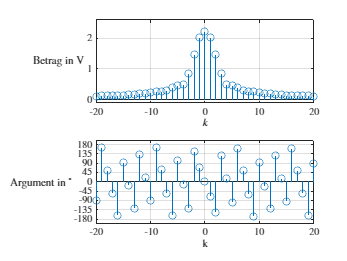

figure
tiledlayout(2, 1)

nexttile
stem(u_p.frsp_idx, u_p.frsp_amp)

grid('on')
xlim([-u_p.frsp_n, u_p.frsp_n])
ylim([-0.1, 2.6])
xlabel('$k$')
ylabel('Betrag in V')
set(get(gca, 'ylabel'), 'Rotation', 0, 'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle')

nexttile
stem(u_p.frsp_idx, u_p.frsp_arg)

grid('on')
xlim([-u_p.frsp_n, u_p.frsp_n])
ylim([-200, 200])
set(gca, 'YTick', -180 : 45 : 180)
xlabel('k')
ylabel('Argument in $^\circ$')
set(get(gca, 'ylabel'), 'Rotation', 0, 'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle')

Darstellung durch Teilschiwngungen


u_p.synth_n = 1000;
u_p.u_k_synth = [u_p.u_k(1), u_p.u_k(2),double(subs(u_p_k_num, k, 2 : u_p.synth_n))];
u_p.u_Amp_Mat = repmat(u_p.u_k_synth.', [1, length(u_p.t)]);
u_p.Harm_Komp_Mat = u_p.u_Amp_Mat .* exp(1j * 2 * pi / u_p.T * (0 : u_p.synth_n)' * u_p.t);


u_p.Harm_Mat = zeros(size(u_p.Harm_Komp_Mat));
u_p.Harm_Mat(1, :) = u_p.Harm_Komp_Mat(1, :);
u_p.Harm_Mat(2 : end, :) = u_p.Harm_Komp_Mat(2 : end, :) + conj(u_p.Harm_Komp_Mat(2 : end, :));

u_p.part_Mat = cumsum(u_p.Harm_Mat, 1);


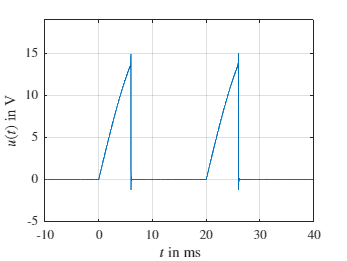

figure

plot(u_p.t * 1e3, u_p.part_Mat(end, :))
grid('on')
xlim([u_p.t(1) * 1e3, u_p.t(end) * 1e3])
ylim([-5, 19])
xlabel('$t$ in ms')
ylabel('$u(t)$ in V')

set(get(gca, 'ylabel'), 'Rotation', 90, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom')

## Berechnung Kenngrößen

**Effektivwert**

u_p_eff = sqrt(1 / T * int(((U_p * sin( pi * f *t))^2), t, [0, t_a]))

$$u\_p\_eff = \frac{U_{p}\,\sqrt{\frac{t_{a}}{2}-\frac{\sin\left(2\,\pi \,f\,t_{a}\right)}{4\,f\,\pi }}}{\sqrt{T}}$$

u_p_eff_num = double(subs(u_p_eff, [T, U_p, f, t_a], [u_p.T, u_p.U_p,u_p.f, u_p.t_a]))

u_p_eff_num = 4.6264

**arithmetischer Mittelwert**

u_p_arith =1 / T * int((U_p * sin( pi * f *t)), t, [0, t_a])

$$u\_p\_arith = \frac{2\,U_{p}\,{\sin\left(\frac{\pi \,f\,t_{a}}{2}\right)}^{2}}{T\,f\,\pi }$$

u_p_arith_num = double(subs(u_p_arith, [T, U_p, f, t_a], [u_p.T, u_p.U_p,u_p.f, u_p.t_a]))

u_p_arith_num = 2.2267

**Klirrfaktor**

Um den Klirrfaktor zu berechnen wird der Effektivwert der Oberschwingungen, Effektivwert des

Wechselanteils und der Effektivwert der Grundwelle benötigt

Effektivwert Wechselanteil

u_p_eff_w = sqrt(u_p_eff^2 - u_p_0^2);
u_p_eff_w = simplify(u_p_eff_w)

$$u\_p\_eff\_w = U_{p}\,\sqrt{\frac{\frac{t_{a}}{2}-\frac{\sin\left(2\,\pi \,f\,t_{a}\right)}{4\,f\,\pi }}{T}-\frac{{\left(\cos\left(\pi \,f\,t_{a}\right)-1\right)}^{2}}{T^{2}\,f^{2}\,\pi^{2}}}$$

u_p_eff_w_num = double(subs(u_p_eff_w, [T, U_p, f, t_a, omega_0], [u_p.T, u_p.U_p,u_p.f, u_p.t_a, pi * u_p.f]))

u_p_eff_w_num = 4.0552

Effektivwert Grundwelle

u_p_eff_gw = sqrt(2) * abs(u_p.u_k_synth(2));
u_p_eff_gw_num = double(subs(u_p_eff_gw, [T, U_p, f, t_a, omega_0], [u_p.T, u_p.U_p,u_p.f, u_p.t_a, pi * u_p.f]))

u_p_eff_gw_num = 2.8460

Berechnung Effektivwert Oberschwingungen

u_p_eff_ow = sqrt(u_p_eff_w^2 - u_p_eff_gw^2);
u_p_eff_ow_num = double(subs(u_p_eff_ow, [T, U_p, f, t_a, omega_0], [u_p.T, u_p.U_p,u_p.f, u_p.t_a, pi * u_p.f]))

u_p_eff_ow_num = 2.8888

Berechnung Klirrfaktor

u_p_klirr = u_p_eff_ow_num/u_p_eff_w_num

u_p_klirr = 0.7124

**Grundwellengehalt**

Grundwellengehalt ist das Verhältnis von Effektivwert der Grundwelle zu dem des Wechselanteils

gwg = u_p_eff_gw_num / u_p_eff_w_num

gwg = 0.7018

**Welligkeit**

Welligkeit ist das Verhältnis von Effektivwert der Wechselanteils zum Gleichanteil

well = u_p_eff_w / u_p_0

$$well = \frac{T\,U_{p}\,\sqrt{\frac{\frac{t_{a}}{2}-\frac{\sin\left(2\,\pi \,f\,t_{a}\right)}{4\,f\,\pi }}{T}-\frac{{\left(\cos\left(\pi \,f\,t_{a}\right)-1\right)}^{2}}{T^{2}\,f^{2}\,\pi^{2}}}}{\frac{U_{p}}{f\,\pi }-\frac{U_{p}\,\cos\left(\pi \,f\,t_{a}\right)}{f\,\pi }}$$

well_num = double(subs(u_p_eff_w, [T, U_p, f, t_a, omega_0], [u_p.T, u_p.U_p,u_p.f, u_p.t_a, pi * u_p.f]))

well_num = 4.0552

**Schwingungsgehalt**


$$s=\frac{U_w }{U}$$


sg_num = double(u_p_eff_w_num / u_p_eff_num)

sg_num = 0.8765

sichern der Daten

u_p muss Aufgrund der Größe seperat gespeichert werden

save('u_p.mat', 'u_p', '-v7.3')
save("Aufgabe3")